clear all, close all, clc

## HW02-0 (Lec 2)

If an individual is exposed in a photon flux of 7,500 cm-2 s-1, calculate the following (note graph attached)

- Dose from a field with rotational symmetry having 662 keV photons for 35 minutes.

- What would the activity (in mCi) be of a point source at 2 m have to attain this flux if the source had a gamma branching ratio of 0.8?

- Dose rate from a 10 MeV photon field at a flux of 10,000 cm-2 s-1.

- Dose rate in isotropic symmetry for 50 keV photons from a bare 1 Ci point source at 10 meter.

#### 1

Given

ph =  7500;         % flux; cm^-2.s^-1
t = 35*60;          % exposure time; sec
Ph = ph *t          % fluence; cm^-2

Ph = 15750000

E_p = 0.662;        % photon energy; MeV

Now, from the following figure we have, for given photon energy-

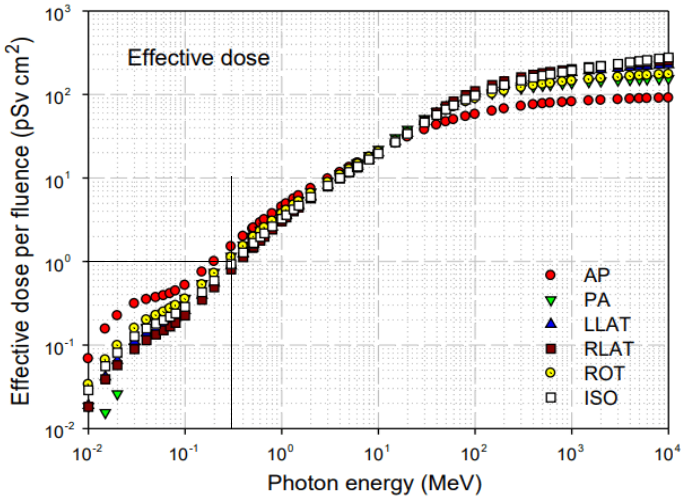

the effective-dose per fluence is

D_Ph = 1;          % eff' dose per fluence; pSv.cm^2
D = D_Ph *Ph       % dose; pSv

D = 15750000

D = D*1e-12        % dose; Sv

D = 1.5750e-05

(Ans)

### 2

$\phi \;=\;\frac{A\;N}{4\pi \;r^2 }$        $\phi =$ flux; $A=$ Activity; $N=$ Branching ratio

ph = 7500;          % flux; cm^-2.s^-1
r = 2*100;          % distance of plane; cm
N = 0.8;            % branching ratio

So, we have

A = ph *(4*pi*r^2) /N   % activity; ds/s (Bq)

A = 4.7124e+09

 Bq_Cu = 37e9;          % constant, Bq/Cu
A = A/Bq_Cu             % activity; Cu

A = 0.1274

(Ans)

#### 3

For dose-rate calculation, the time to consider of exposure should be 1 sec

ph =  10000;        % flux; cm^-2.s^-1
t = 1;              % exposure time; sec
Ph = ph *t          % fluence; cm^-2

Ph = 10000

E_p = 10;           % photon energy; MeV

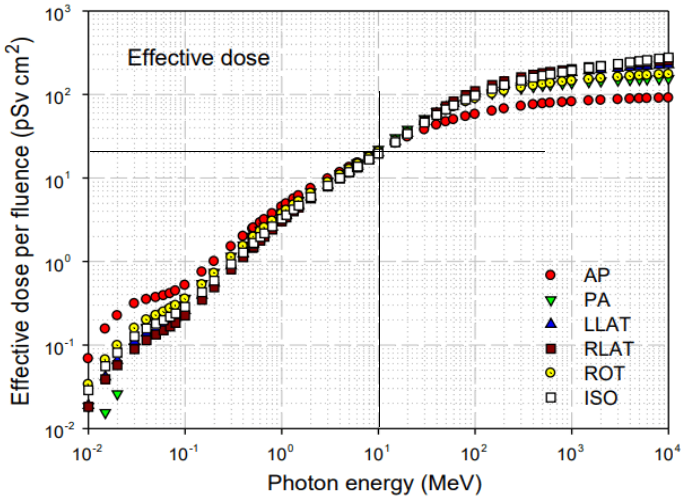

D_Ph = 20;           % e-dose per fluence; pSv.cm^2
D_r = D_Ph *Ph       % dose-rate; pSv/s

D_r = 200000

(Ans)

#### 4

Given

E_p = 0.05;           % photon energy; MeV

Now, let's find the fluence for this for 1 sec

A = 1 *37e9;        % source activity; Bq
r = 10*100;         % cm
ph = A/(4*pi*r^2)   % flux; cm^-2.s^-1

ph = 2.9444e+03

Ph = ph *1;         % fluence; cm^-2

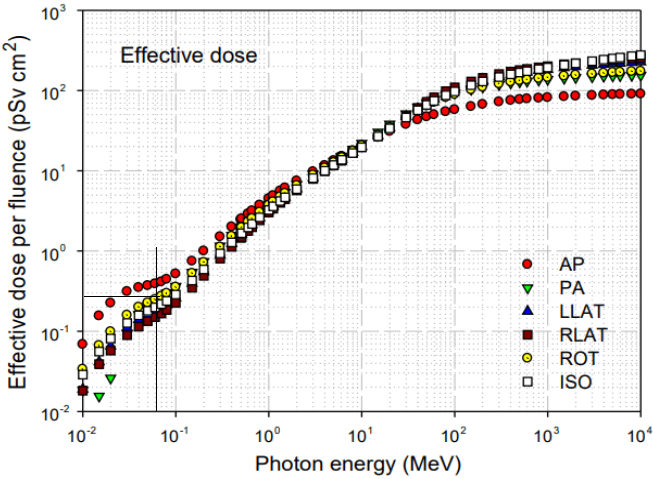

D_Ph = 0.3;         % e-dose per fluence; pSv.cm^2
D_r = D_Ph *Ph      % dose-rate; pSv/s

D_r = 883.3099

(Ans)

## HW02-01

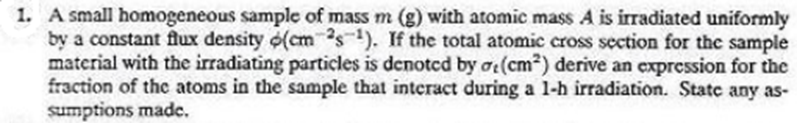

Here, the number of atoms being irradiated


$$N_{\textrm{ar}} =\phi \;\sigma_t \;{60}^2$$


Here, $\phi =$ flux density;  $\sigma_t =$ cross section of irradiating particles

${60}^2$ = sec/hour

And, no. of atom in the sample


$$N=\frac{m\;N_a }{A}$$


$m=$ mass; $N_a =$ Avogadro's number; $A=$ atomic mass

So, the fraction would be-


$$f=\frac{N}{N_{\textrm{ar}} }$$



$$f=\frac{\phi \;\sigma_t \;{60}^2 A}{m\;N_a }$$


This is valid for surface interaction. Deep interactions needs LAC to be introduced

(Ans)

## **HW02-02**

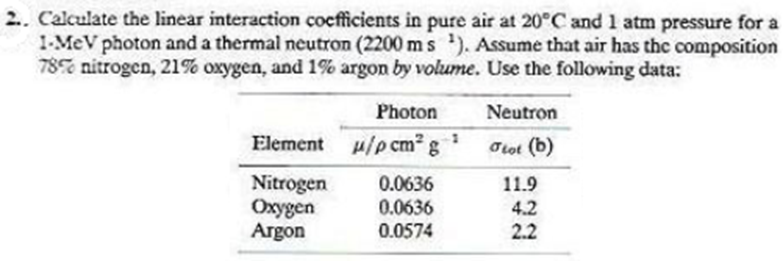

**Part 1, for Photon**

First, for 1 MeV photon, let's find the weight fraction of individual gases in air.

n_N = 0.78;         % no. fraction, N
n_O = 0.21;         % no. fraction, O
n_Ar = 0.01         % no. fraction, Ar

n_Ar = 0.0100

Now, let's find the total weight of the air- normalized by its constituents. 

w_T =  14*n_N + 16*n_O + 40*n_Ar      % air's weight, gm/mol

w_T = 14.6800

So, the weight fraction would be-

w_N = 0.78*14/w_T       % weight fraction of N; -

w_N = 0.7439

w_O = 0.21*16/w_T       % weight fraction of O; -

w_O = 0.2289

w_Ar = 0.01*40/w_T      % weight fraction of Ar; -

w_Ar = 0.0272

So, LAC can be given by

$\Sigma_p =w_N {\left(\frac{\mu \;}{\rho \;}\right)}_N +w_O {\left(\frac{\mu \;}{\rho \;}\right)}_O +w_{\textrm{Ar}} {\left(\frac{\mu \;}{\rho \;}\right)}_{\textrm{Ar}}$    $\Sigma_p =$ MEAC for photon

Or, $\Sigma_p =w_N {\;\mu }_{\textrm{mN}} +w_O {\;\mu }_{\textrm{mO}} +w_{\textrm{Ar}} {\;\mu }_{\textrm{mAr}}$;     ${\;\mu }_m$ = total (mass) attenuation coefficient

mu_m_N = 0.0636;        % MEAC., N; cm^2/g
mu_m_O = 0.0636;        % MEAC., O; cm^2/g
mu_m_Ar = 0.0574;       % MEAC., Ar; cm^2/g

mu_m_a = mu_m_N *w_N + mu_m_O *w_O + mu_m_Ar *w_Ar

mu_m_a = 0.0634

                        % MEAC of air; cm^2/g

So, for LAC


$$\mu_a =\Sigma_p *{\rho \;}_a$$


rho_a = 1.23e-3;         % air density; g/cm^3
mu_ap = rho_a * mu_m_a   % LAC air, photon; cm^-1

mu_ap = 7.8020e-05

(Ans)

**Part 2, For Neutron**

Now, let's find the LAC for thermal neutron of 2200 ms^-1

$\mu_N =\sum_i \;\sigma_i \;N_i$        Here, $\sigma$= CS and N = no. density of gas

sg_N = 11.9e-28;        % cross-section, N; m^-2
sg_O = 4.2e-28;         % cross-section, O; m^-2
sg_Ar = 2.2e-28;        % cross-section, Ar; m^-2

Let's find the total volume of air

R = 8.314;          % gas const.; JK^-1.mol^-1
P = 1*101325;       % pressure; Pa
T = 20 + 273;       % temperature; K
V = R*T/P           % air volume; m^3/mol

V = 0.0240

Now, let's calculate the individual no. density of gases

Na = 6.022e23;      % Avogadro's no.; no./mol
N_N = n_N *Na/V     % no. density of N; no./m^3

N_N = 1.9538e+25

N_O = n_O *Na/V     % no. density of O; no./m^3

N_O = 5.2602e+24

N_Ar = n_Ar *Na/V   % no. density of Ar; no./m^3

N_Ar = 2.5048e+23

Now, let's find the LAC for neutron in air-

mu_an = sg_N *N_N + sg_O *N_O  + sg_Ar *N_Ar;    % LAC air, for Neutron; 1/m
mu_an = mu_an * 0.01            % LAC air, cm^-1

mu_an = 2.5514e-04

(Ans)

## HW02-07

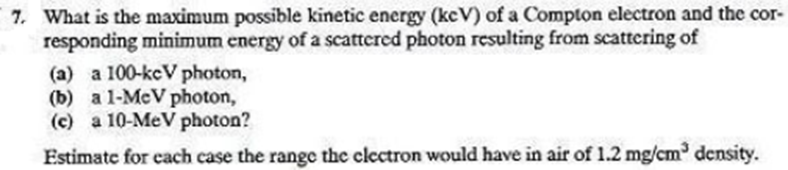

We know,

me = 9.1e-31;           % electron mass; kg
c = 3e8;                % light velocity; m/s
me_r = me*c^2;          % e' rest mass; J
  J_KeV = 1.6e-16;      % J/KeV
me_r = me_r /J_KeV      % e' rest mass; KeV

me_r = 511.8750

Now, we know-

  Here, E' = scattered photon energy

#### a)

Given,

E = 100;                    % photon energy; KeV
E_mn = E /(1 + 2*E/me_r)    % min' scattered photon energy; KeV

E_mn = 71.9052

(Ans)

T = E - E_mn                % max' KE of compton electron; KeV

T = 28.0948

(Ans)

Now, for range, it is-


$$\rho \;\Lambda =\delta \;T^n$$
 

Here,$\rho =$ density; $\Lambda =$ range; $\delta ,n$ constants 

Now, values of $\rho \;\Lambda$ for air comes from the following diagram-

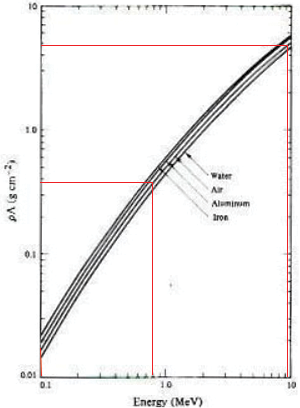 Figure: 2.07

Now, let's find the range. Here, for T = 0.028 MeV, this is not in the diagram. So, let's the value to be 1/10th of what for 0.1 MeV of electron energy. So-

T_e = 0.028;            % e' KE; MeV
rh_Lm = 0.015/10;       % range-density; g.cm^-2
rh = 1.2e-3;            % air density, given; g.cm^-3
Lm = rh_Lm/rh           % range; cm

Lm = 1.2500

(Ans)

#### b)

E = 1;                      % photon energy; MeV
E = E*1e3;                  % KeV
E_mn = E /(1 + 2*E/me_r)    % min' scattered photon energy; KeV

E_mn = 203.7820

(Ans)

T = E - E_mn                % max' KE of compton electron; KeV

T = 796.2180

(Ans)

Now, let's find the range-

T_e = 0.796;            % e' KE; MeV
rh_Lm = 0.375;          % range-density; g.cm^-2
rh = 1.2e-3;            % air density, given; g.cm^-3
Lm = rh_Lm/rh           % range; cm

Lm = 312.5000

(Ans)

#### c)

E = 10;                     % photon energy; MeV
E = E*1e3;                  % KeV
E_mn = E /(1 + 2*E/me_r)    % min' scattered photon energy; KeV

E_mn = 249.5506

(Ans)

T = E - E_mn                % max' KE of compton electron; KeV

T = 9.7504e+03

(Ans)

T_e = 9.75;             % e' KE; MeV
rh_Lm = 3.8;            % range-density; g.cm^-2
rh = 1.2e-3;            % air density, given; g.cm^-3
Lm = rh_Lm/rh           % range; cm

Lm = 3.1667e+03

(Ans)

## HW02-11

From eq-2.63 of textbook, we get

$\rho \;\Lambda =\delta \;T^n$            (2.63)

Here, $\Lambda \;$indicates the stopping range of electron, within the shielding material

$\rho \;\Lambda \left(g\;{\textrm{cm}}^{-2} \right)$ also represents the range

The values of constants $\delta$ and n are given in the following table

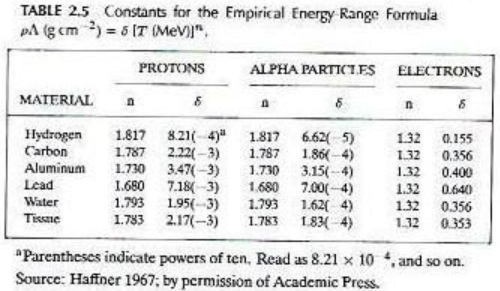

Now, as the values for iron are not given here, let's use Aluminum instead.

#### (a) for Electron

rho = 2.7;          % density, Al; gm/cm^-3
T = 10;             % kin' energy; MeV
dl = 0.4;           % const
n = 1.32;

So, $\rho \;\Lambda$ here-

rh_Lm_e = dl *T^n       % range, e'; g.cm^-2

rh_Lm_e = 8.3572

verifying it agains fig 2.17 of the textbook, we can see, the $\rho \;\Lambda$ values are not very similar. Because, the value here seems 0.08 gm.cm^-2

#### 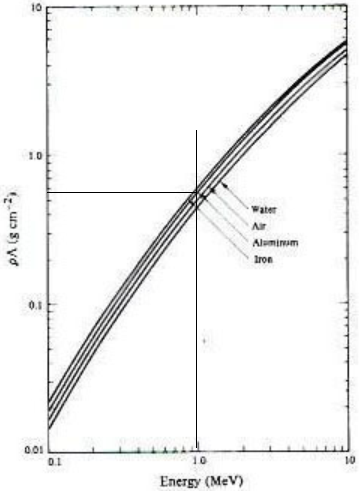

Then, the thickness of Al shield for this-

Lam_e = rh_Lm_e/rho         % range/thickness, e'; cm

Lam_e = 3.0953

(Ans)

#### (b) for alpha particle

rho = 2.7;          % density, Al; gm/cm^-3
T = 10;             % kin' energy; MeV
dl = 3.15e-4;       % const
n = 1.73;

So, $\rho \;\Lambda$ here-

rh_Lm_a = dl *T^n     % range, e'; g.cm^-2

rh_Lm_a = 0.0169

Then, the thickness-

Lam_a = rh_Lm_a/rho         % range/thickness, e'; cm

Lam_a = 0.0063

(Ans)

#### (c) for Proton

dl = 3.47e-3;       % const
n = 1.673;

So, we have-

rh_Lm_p = dl *T^n        % range, proton; g.cm^-2

rh_Lm_p = 0.1634

verifying it agains fig 2.16 of the textbook, we can see, the $\rho \;\Lambda$ values are similar

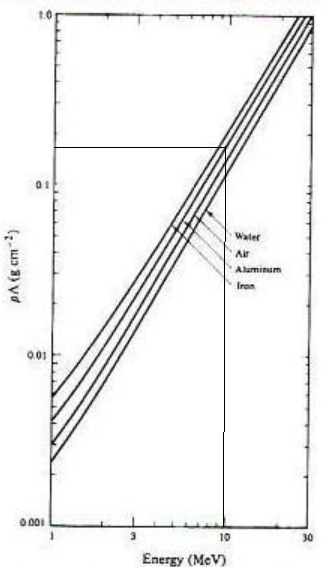

Then, let's find the thickness of the Al shield for this.

Lam_p = rh_Lm_p/rho         % thickness, proton; cm

Lam_p = 0.0605

(Ans)

## HW02-23

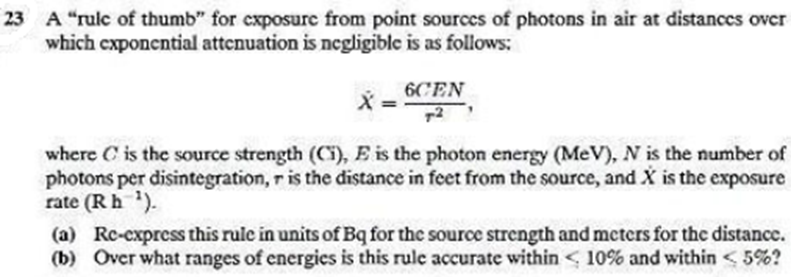

**(a)**

Given

$\dot{X} =\frac{6\textrm{CEN}}{r^2 }$ Here, C is in Ci, E in MeV,  r is in feet, N is branching

Here we know,

1 Ci = 3.7e(10) Bq

1 ft = 0.305 m

Now, we have


$$\dot{X} =6\frac{\textrm{CEN}}{r^2 }=6\frac{\left(3\ldotp 7\times {10}^{10} \right)\textrm{CEN}}{{\left(0\ldotp 305r\right)}^2 }$$



$$\dot{X} =2\ldotp 387\times {10}^{12} \frac{\textrm{CEN}}{r^2 }$$


**(b)**

Let assume-

C = 1;              % ; Ci
r = 1;              % ; ft
N = 1;              % photon branching
E = 1;              % photon energy; MeV

Now, we have this equation,


$$\dot{X} =6\frac{\textrm{CEN}}{r^2 }$$


which can be rearranged as-


$$\frac{\dot{X} r^2 }{\mathrm{CEN}}=6=\mathrm{Cs}$$


Let the constant value is cs. so, we have for unit exposure-

x_dt = 6;           % unit exposure, R.h^-1

Then, the value of constant for this value of exposure would be-

cs = x_dt*r^2 /(C*E*N)

cs = 6

So, for E = 1 MeV, this is correct. Now, let's vary the values of E from 0.1 to 3 MeV

E = linspace(0.1, 3, 100);          % MeV

Then, again find the constant's value for this variation of E

cs = x_dt*r^2 ./(C*E*N);

Now, let's plot the values for 10% accuracy of the constant which ranges from 5.4 to 6.6. 

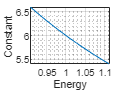

figure(1)
plot(E,cs), grid on, grid minor
xlabel('Energy'); ylabel('Constant')
ylim([5.4 6.6])

So, we get from this plot, for value of 0.91 < E < 1.11 MeV of E, this constant's value lies within 10% of 6.

Now, let's plot the values for 5% accuracy of the constant which ranges from 5.7 to 6.3. 

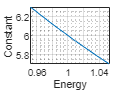

figure(2)
plot(E,cs), grid on, grid minor
xlabel('Energy'); ylabel('Constant')
ylim([5.7 6.3])

So, the figure shows taht for value of approximately 0.95 < E < 1.055 MeV of E, this value lies within 5% of 6.